# General system details

sampleRateHz = 1e6; % Sample rate
samplesPerSymbol = 1;
frameSize = 2^10;
numFrames = 100;
numSamples = numFrames*frameSize; % Samples to simulate
modulationOrder = 2;
filterUpsample = 4;
filterSymbolSpan = 8;

## Impairments

snr = 15;
frequencyOffsetHz = 1e5; % Offset in hertz
phaseOffset = 0; % Radians

## Generate symbols

data = randi([0 samplesPerSymbol], numSamples, 1);
mod = comm.DBPSKModulator();
modulatedData = mod.step(data);

## Add TX Filter

TxFlt = comm.RaisedCosineTransmitFilter('OutputSamplesPerSymbol', filterUpsample, 'FilterSpanInSymbols', filterSymbolSpan);
filteredData = step(TxFlt, modulatedData);

## Add noise

noisyData = awgn(filteredData,snr);%,'measured');

## Setup visualization object(s)

sa = spectrumAnalyzer('SampleRate',sampleRateHz,'ShowLegend',true);

## Model of error

Add frequency offset to baseband signal

% Precalculate constant(s)
normalizedOffset = 1i.*2*pi*frequencyOffsetHz./sampleRateHz;

offsetData = zeros(size(noisyData));
for k=1:frameSize:numSamples*filterUpsample
    
    % Create phase accurate vector
    timeIndex = (k:k+frameSize-1).';
    freqShift = exp(normalizedOffset*timeIndex + phaseOffset);
    
    % Offset data and maintain phase between frames
    offsetData(timeIndex) = (noisyData(timeIndex).*freqShift);
    
    % Visualize Error
    step(sa,[noisyData(timeIndex),offsetData(timeIndex)]);pause(0.1); %#ok<*UNRCH>
    
end

## Plot

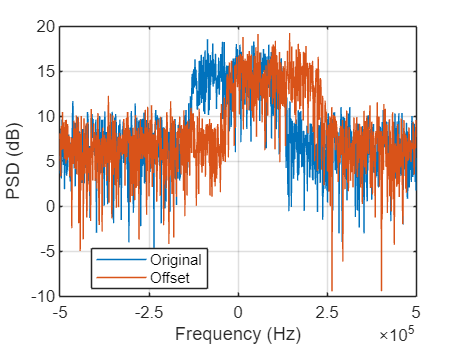

df = sampleRateHz/frameSize;
frequencies = -sampleRateHz/2:df:sampleRateHz/2-df;
spec = @(sig) fftshift(10*log10(abs(fft(sig))));
h = plot(frequencies, spec(noisyData(timeIndex)),...
    frequencies, spec(offsetData(timeIndex)));
grid on;xlabel('Frequency (Hz)');ylabel('PSD (dB)');
legend('Original','Offset','Location','Best');
NumTicks = 5;L = h(1).Parent.XLim;
set(h(1).Parent,'XTick',linspace(L(1),L(2),NumTicks))